load("CFD_confined_TSR_1_1.mat")
rt = 2.042;
Uinf = 0.91;
lam = 1.1;
%lam = 1.9;
Omega = lam*Uinf/rt;
syms t;
Ry2 = [cosd(t) sind(t); -sind(t) cosd(t)];
GC = struct;
GC.alphaP = 6;
GC.lambda = lam;
num = length(theta)

num = 62

Xrots = struct;
Yrots = struct;
Pins = struct;

for k=1:num
    alpha = theta(k);
    Xrot3 = zeros(sz);
    Yrot3 = zeros(sz);
    for j = 1:sz
        T3 = [X(:,1)';Y(:,j)'];
        XYRy2 = Ry2*T3; 
        res = subs(XYRy2,t,alpha);
        Xrot3(:,j) = res(1,:);
        Yrot3(:,j) = res(2,:);
    end
    Xrots(k).Xrot3 = Xrot3;
    Yrots(k).Yrot3 = Yrot3;
end

for k = 1:num
    alpha = theta(k);
    qc = 2.042*[sind(theta(k));cosd(theta(k))];
    qc = Ry2*qc;
    qc = subs(qc,t,-alpha);
    qc = double(qc);
    Xrot3 = Xrots(k).Xrot3;
    Yrot3 = Yrots(k).Yrot3;
    [Pin, Pa] = Points2(qc,1,0.5,Xrot3,Yrot3);
    %[Cin, Ca] = Circle2(qc,1.6,Xrot3,Yrot3);
    Pins(k).Pin = Pin;
    Pins(k).Pa = Pa;
end

ur = zeros(num,1);
for k = 1:num
p1 = double(subs(Ry2*Pins(k).Pa(:,1),t,theta(k)));
p1r = round((p1+12)*4.5)
ur(k) = norm(flow_data(k).u(p1r)/Uinf);
%norm(flow_data(k).u(logical(Pins(k).Pin)))/Uinf;
end

p1r =     52
    59


p1r =     52
    59


p1r =     53
    59


p1r =     53
    59


p1r =     54
    59


p1r =     54
    59


p1r =     55
    59


p1r =     55
    59


p1r =     56
    59


p1r =     56
    59


p1r =     57
    58


p1r =     57
    58


p1r =     58
    58


p1r =     58
    57


p1r =     58
    57


p1r =     59
    57


p1r =     59
    56


p1r =     59
    56


p1r =     59
    55


p1r =     59
    54


p1r =     59
    54


p1r =     59
    53


p1r =     59
    53


p1r =     59
    52


p1r =     59
    52


p1r =     58
    51


p1r =     58
    51


p1r =     58
    50


p1r =     57
    50


p1r =     57
    50


p1r =     57
    49


p1r =     56
    49


p1r =     56
    49


p1r =     55
    49


p1r =     55
    49


p1r =     54
    49


p1r =     53
    49


p1r =     53
    49


p1r =     52
    49


p1r =     52
    49


p1r =     51
    49


p1r =     51
    50


p1r =     51
    50


p1r =     50
    51


p1r =     50
    51


p1r =     50
    51


p1r =     49
    52


p1r =     49
    52


p1r =     49
    53


p1r =     49
    53


p1r = 2×1
    49
    54


p1r = 2×1
    49
    54


p1r = 2×1
    49
    55


p1r = 2×1
    49
    56


p1r = 2×1
    49
    56


p1r = 2×1
    49
    57


p1r = 2×1
    50
    57


p1r = 2×1
    50
    57


p1r = 2×1
    50
    58


p1r = 2×1
    51
    58


p1r = 2×1
    51
    58


p1r = 2×1
    52
    59


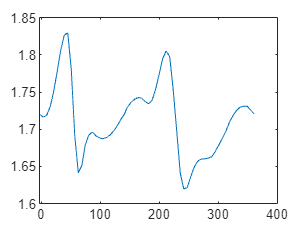

plot(theta,ur)